clear all
close all
clc
% set tuid and amplitude
tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]
rb = 1000 * (tuid(8) + 3);      % Bit rate hz

## Data stream generation

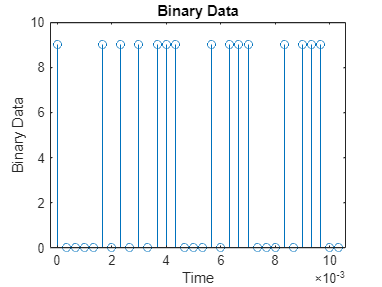

% Parameters

Tb = 1/rb;      % Bit interval
fs = 100*rb;    % Sampling freq (Sampling Rate)
Ts = 1/fs;      % Sampling interval

M = 2;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol (Symbol Rate)

N = 32;
t1 = (0:N-1)*Tb;
binary = A*randi([0,M-1],1,N);

figure(1)
stem(t1,binary)
xlabel('Time')
ylabel('Binary Data')
title('Binary Data')

## Task 1 Plot the original signal

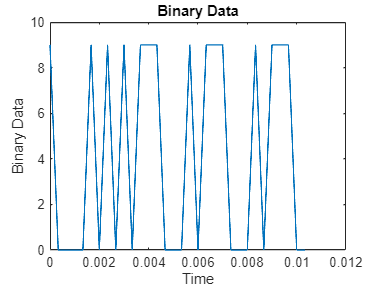

% Plot the original signal
figure(2)
plot(t1,binary)
xlabel('Time')
ylabel('Binary Data')
title('Binary Data')

## Increase Sample Rate

signal = repelem(binary,floor(Tb/Ts));
t = (0:length(signal)-1)*Ts;

## Polar Non Return to Zero

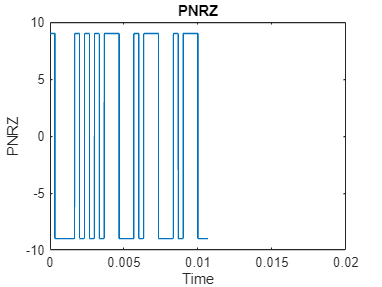

% Encoded signal
bnrz = 1*(2 * (binary - A/2));
signal_bnrz = repelem(bnrz, floor(Tb/Ts));
figure(3)
plot(t,signal_bnrz)
xlim([0 .02])
xlabel('Time')
ylabel('PNRZ')
title('PNRZ')

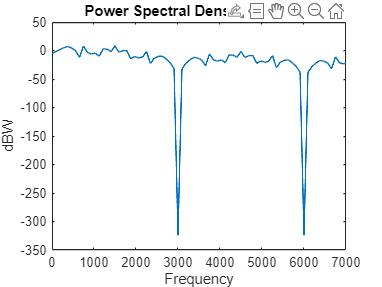

% PSD
[f,psd]=myfft(signal_bnrz,length(signal),fs);
psd_dbw = 10*log10(psd);
figure(4)
plot(f(f>=0),psd_dbw(f>=0));
xlim([0,7000])
xlabel('Frequency')
ylabel('dBW')
title('Power Spectral Density of PNRZ ')

% Frequency Spectrum 
scope2 = dsp.SpectrumAnalyzer();

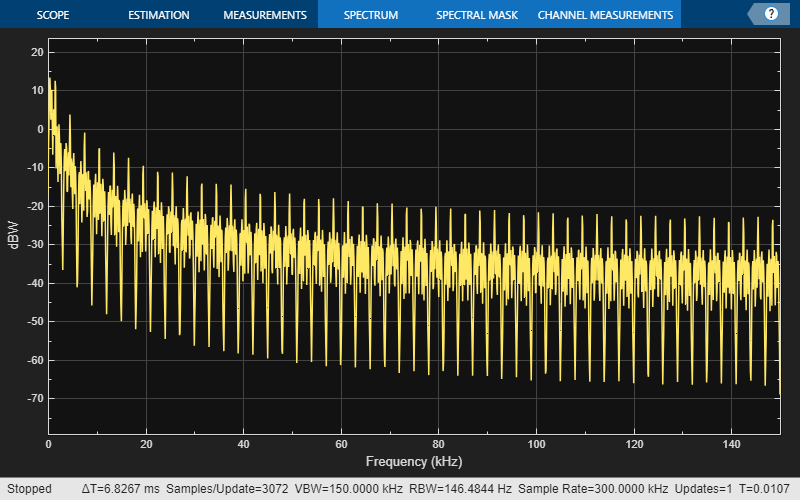

scope2.SampleRate = fs;
scope2.PlotAsTwoSidedSpectrum = false;
scope2.SpectrumUnits = "dBW";
scope2(signal_bnrz');
scope2.Name = 'Polar RZ';
release(scope2);

## Differential

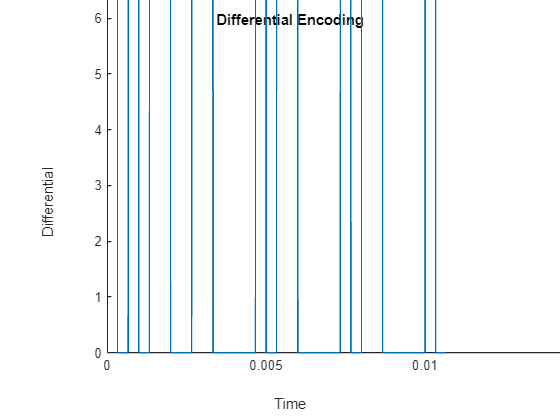

% encoded signal
dunrz = zeros(size(binary));

ref = 1;
for c =1:length(binary)
    dunrz(c) = not(xor(ref,binary(c)));
    ref = dunrz(c);
end

signal_dunrz =A * repelem(dunrz, floor(Tb/Ts));       % Change indices to the new sampling frequency

figure(5)
plot(t, signal_dunrz);
xlim([0 .02])
xlabel('Time')
ylabel('Differential')
title('Differential Encoding')

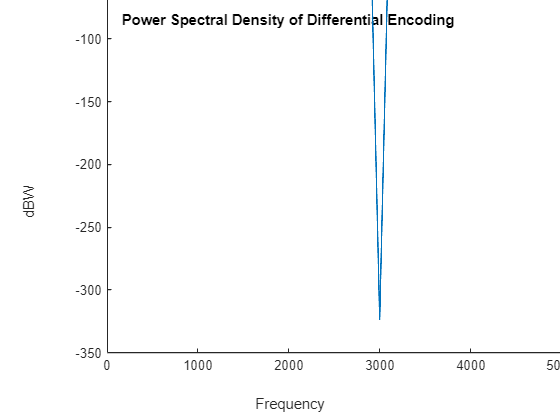

%PSD
figure(6)
plot(f(f>=0),psd_dbw(f>=0));
xlim([0,7000])
xlabel('Frequency')
ylabel('dBW')
title('Power Spectral Density of Differential Encoding ')

% Frequency Spectrum
scope5 = dsp.SpectrumAnalyzer();

scope5.SampleRate = fs;
scope5.PlotAsTwoSidedSpectrum = false;
scope5.SpectrumUnits = "dBW";
scope5(signal_dunrz');
scope5.Name = 'Differential';
release(scope5);